clear;clc;

N = 400; Ne = round(0.8*N); Ni = N-Ne;
nMems = 10;
nTrials = 1000;
sims_path = fullfile("Data", "N" + num2str(N), "nMems" + num2str(nMems));
sim_folders = dir(sims_path); sim_folders = sim_folders(~ismember({sim_folders.name}, {'.', '..'}));

load(fullfile(sim_folders(end).folder, sim_folders(end).name, 'MemoryRepresentations.mat'))
whos

  Name              Size                Bytes  Class     Attributes

  N                 1x1                     8  double              
  Ne                1x1                     8  double              
  Ni                1x1                     8  double              
  memories         10x1             129297593  struct              
  nMems             1x1                     8  double              
  nTrials           1x1                     8  double              
  sim_folders       1x1                  1134  struct              
  sims_path         1x1                   198  string              



## Trajectory of the probing a memory in sequential learning 

rep = "delays";

R_probe = zeros(nMems, nMems, N);
R_learn = zeros(nMems, nTrials, N);

for mem = 1:nMems
    R_probe(mem, :, :) = eval("memories(mem)." + rep + ".probe");
    R_learn(mem, :, :) = eval("memories(mem)." + rep + ".learning");
end

[coeff, score, latent, tsquared, explained, mu] = pca([reshape(R_probe, nMems*nMems, N); reshape(R_learn, nMems*nTrials, N)]);

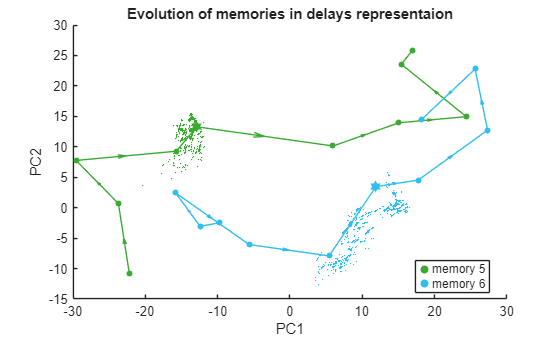

figure; hold on;
cmap = lines(nMems);

pc1 = 1; pc2 = 2;
for mem = 5:6
    r = squeeze(R_probe(mem, :, :));
    r = (r - mu)*coeff;
    
    % plotting the response points of probes
    scatter(r(:, pc1), r(:, pc2), 20, cmap(mem, :), 'filled', 'DisplayName', sprintf('memory %d', mem));
    scatter(r(mem, pc1), r(mem, pc2), 80, cmap(mem, :), 'filled', 'h', 'HandleVisibility', 'off');
    
    % plotting the learnig curve of the mem
    r_learn = squeeze(R_learn(mem, :, :));
    r_learn = (r_learn - mu)*coeff;
    scatter(r_learn(:, pc1), r_learn(:, pc2), 1, cmap(mem, :), 'filled', 'HandleVisibility', 'off')
    
    % plot(r_learn(:, 1), r_learn(:, 2), Color=cmap(mem,:), LineWidth=1);

    % Arrows between consecutive points
    for i = 1:size(r, 1)-1
        dx = r(i+1,pc1) - r(i,pc1);
        dy = r(i+1,pc2) - r(i,pc2);

        % Midpoint
        mx = (r(i+1,pc1) + r(i,pc1)) / 2;
        my = (r(i+1,pc2) + r(i,pc2)) / 2;

        % Draw arrow centered at midpoint with half-length vector
        quiver(mx - dx/2, my - dy/2, dx/2, dy/2, ...
               0, 'Color', cmap(mem,:), 'MaxHeadSize', 0.5, ...
               'AutoScale', 'on', 'HandleVisibility', 'off');
        quiver(mx, my, dx/2, dy/2, ...
               0, 'Color', cmap(mem,:), 'MaxHeadSize', 0.0, ...
               'AutoScale', 'off', 'HandleVisibility', 'off');
    end
end
legend(Location="best");
xlabel(sprintf("PC%d", pc1)); ylabel(sprintf("PC%d", pc2)); 
title(sprintf("Evolution of memories in %s representaion", rep))

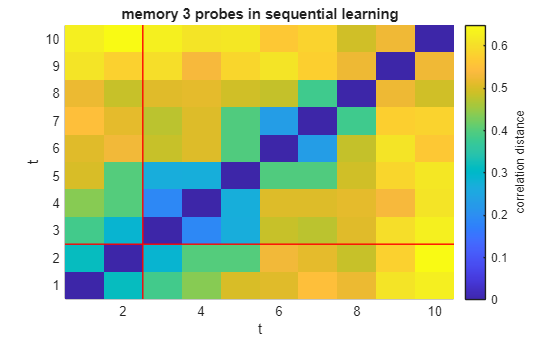

mem = 3; metric = 'correlation';
distMat = squareform(pdist(squeeze(R_probe(mem, :, :)), metric));
figure; hold on;
imagesc(distMat); cb = colorbar(); cb.Label.String = metric + " distance";
title(sprintf("memory %d probes in sequential learning", mem))
plot(mem*[1 1] - 0.5, [0.5 nMems+0.5], 'r-');
plot([0.5 nMems+0.5], mem*[1 1] - 0.5, 'r-');
% plot(mem*[1 1] + 0.5, [0.5 nMems+0.5], 'r-');
% plot([0.5 nMems+0.5], mem*[1 1] + 0.5, 'r-');
xlim([0.5 nMems+0.5]);
ylim([0.5 nMems+0.5]);
xlabel("t")
ylabel("t")

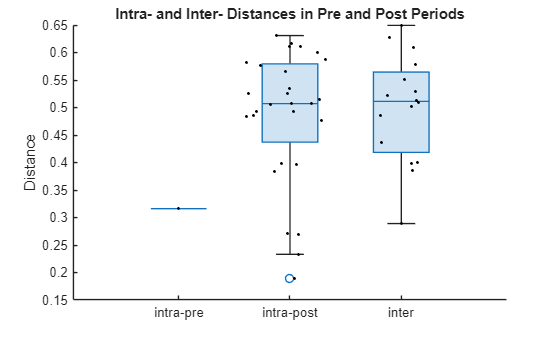

submat = distMat(1:mem-1, 1:mem-1);
temp = submat(triu(true(size(submat)), 1));
d_intra_pre = temp;

submat = distMat(mem:end, mem:end);
temp = submat(triu(true(size(submat)), 1));
d_intra_post = temp;

submat = distMat(1:mem-1, mem:end);
d_inter = submat(:);

% Combine all distances into one vector
d_all = [d_intra_pre(:); d_intra_post(:); d_inter(:)];

% Define group labels
groups = [ ...
    repmat("intra-pre", numel(d_intra_pre), 1);
    repmat("intra-post", numel(d_intra_post), 1);
    repmat("inter", numel(d_inter), 1)
];

% Ensure consistent order of categories
groups = categorical(groups, ["intra-pre", "intra-post", "inter"]);

% Plot
figure; hold on;
boxchart(groups, d_all);
swarmchart(groups, d_all, 5, 'k', 'filled');

ylabel('Distance');
title('Intra- and Inter- Distances in Pre and Post Periods')

# Statistics on Different Memory Probes

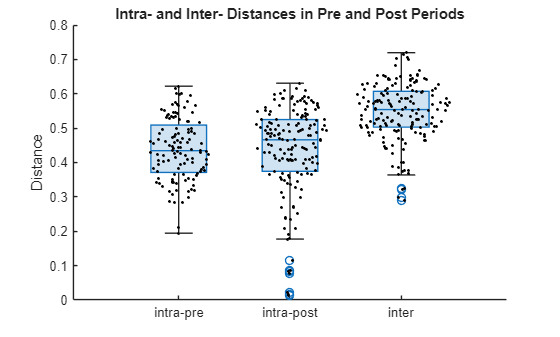

groups = [];
d_all = [];

metric = 'correlation';

for mem = 1:nMems
    distMat = squareform(pdist(squeeze(R_probe(mem, :, :)), metric));
    
    submat = distMat(1:mem-1, 1:mem-1);
    temp = submat(triu(true(size(submat)), 1));
    % d_intra_pre = [d_intra_pre; temp];
    groups = [groups; repmat("intra-pre", numel(temp), 1)];
    d_all = [d_all; temp];

    submat = distMat(mem:end, mem:end);
    temp = submat(triu(true(size(submat)), 1));
    % d_intra_post = [d_intra_post; temp];
    groups = [groups; repmat("intra-post", numel(temp), 1)];
    d_all = [d_all; temp];

    submat = distMat(1:mem-1, mem:end);
    % d_inter = [d_inter; submat(:)];
    groups = [groups; repmat("inter", numel(submat(:)), 1)];
    d_all = [d_all; submat(:)];
end

% Ensure consistent order of categories
groups = categorical(groups, ["intra-pre", "intra-post", "inter"]);

% Plot
figure; hold on;
% violinplot(groups, d_all, ...        
%     'UserData', true);
boxchart(groups, d_all);

swarmchart(groups, d_all, 5, 'k', 'filled');

ylabel('Distance');
title('Intra- and Inter- Distances in Pre and Post Periods')

# Consecutive self distance of a memory  

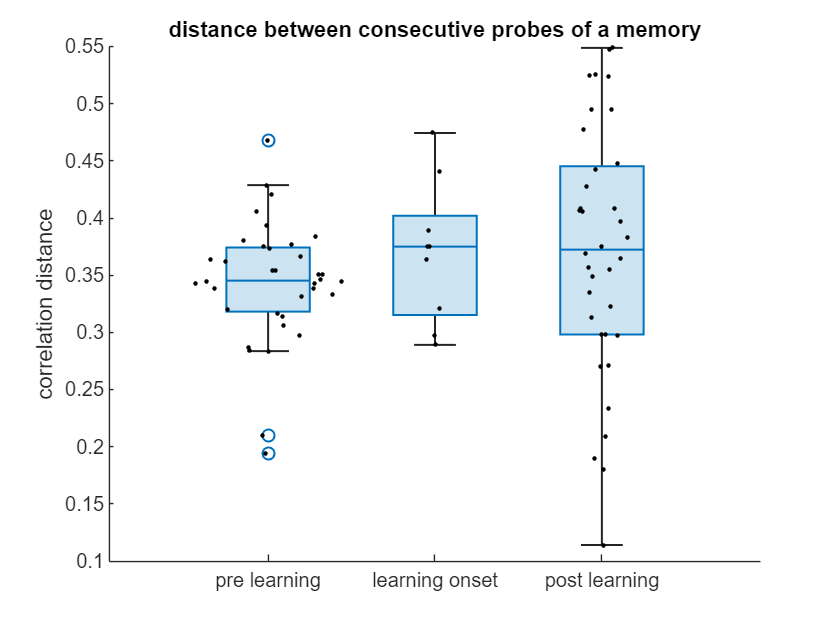


d_pre = [];
d_post = [];
d_learn = [];

metric = ['correlation.' ...
    ''];
for mem = 2:nMems
    distMat = squareform(pdist(squeeze(R_probe(mem, :, :)), metric));
    d1 = diag(distMat, 1);
    d_pre = [d_pre, d1(1:mem-2)'];
    d_learn = [d_learn, d1(mem-1)'];
    d_post = [d_post, d1(mem:end)'];
end

d_all = [d_pre, d_learn, d_post]';  % Convert to column vector
groups = [ ...
    repmat("pre learning", length(d_pre), 1);
    repmat("learning onset", length(d_learn), 1);
    repmat("post learning", length(d_post), 1) ...
];
groups = categorical(groups, ["pre learning", "learning onset", "post learning"]);

figure; hold on;
boxchart(categorical(groups), d_all);
% Overlay scatter (swarm-style)
swarmchart(categorical(groups), d_all, 5, 'k', 'filled');  % 5 = marker size, 'k' = black

title(sprintf('distance between consecutive probes of a memory'));
ylabel(sprintf("%s distance", metric))

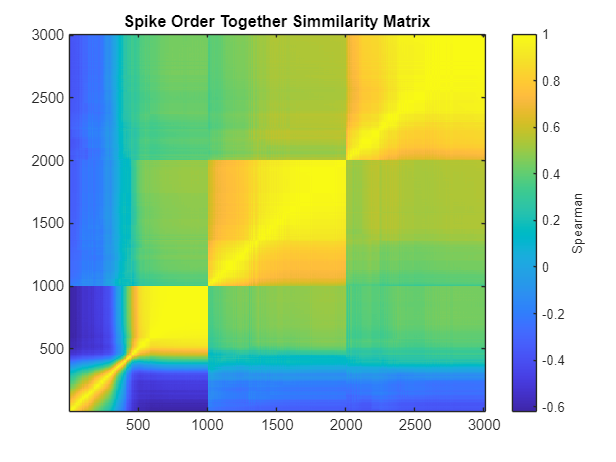

%% Simmilarity matrix of order vector 
figure;
imagesc(1-squareform(pdist(orders_separate(:, 1:Ne), "spearman")));
title("Spike Order Separate Simmilarity Matrix");
cb = colorbar(); cb.Label.String = "Spearman"; 
set(gca, 'ydir', 'normal');

figure;
imagesc(1-squareform(pdist(orders_together(:, 1:Ne), "spearman")));
title("Spike Order Together Simmilarity Matrix");
cb = colorbar(); cb.Label.String = "Spearman";
set(gca, 'ydir', 'normal');

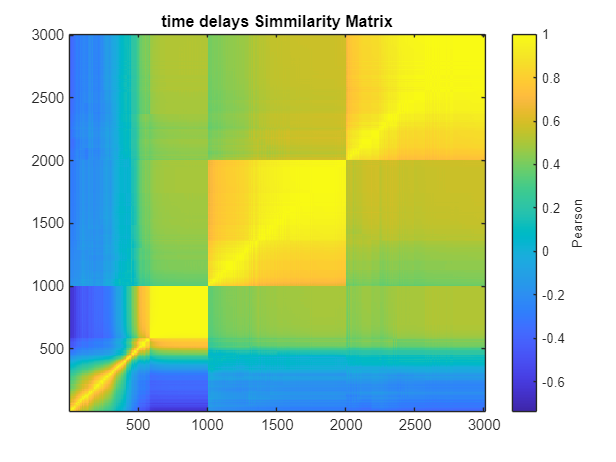

%% Simmilarity matrix of spike counts and time delays representations 

figure;
dist_mat = 1-squareform(pdist(delays(:, 1:Ne), "correlation"));
imagesc(dist_mat);
title("time delays Simmilarity Matrix");
cb = colorbar(); cb.Label.String = "Pearson";
set(gca, 'ydir', 'normal');

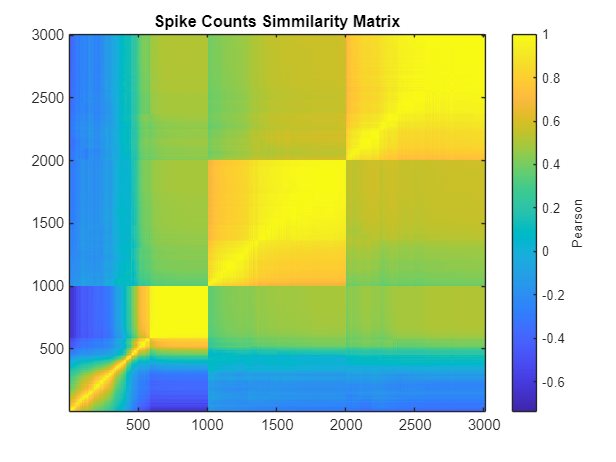


figure;
spikeCount_dist_mat = 1-squareform(pdist(spike_counts(:, 1:Ne), "correlation"));
imagesc(dist_mat);
title("Spike Counts Simmilarity Matrix");
cb = colorbar(); cb.Label.String = "Pearson";
set(gca, 'ydir', 'normal');

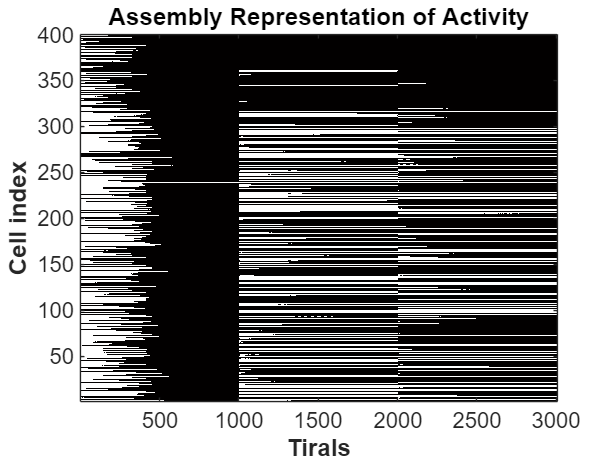


%% Assembly Activities Representation
assemblies = spike_counts ~= 0;
figure; imagesc(~assemblies'); colormap('hot');
xlabel("Tirals", 'FontWeight','bold'); ylabel("Cell index", 'FontWeight','bold'); title("Assembly Representation of Activity");
set(gca, 'ydir', 'normal', 'FontSize', 15);

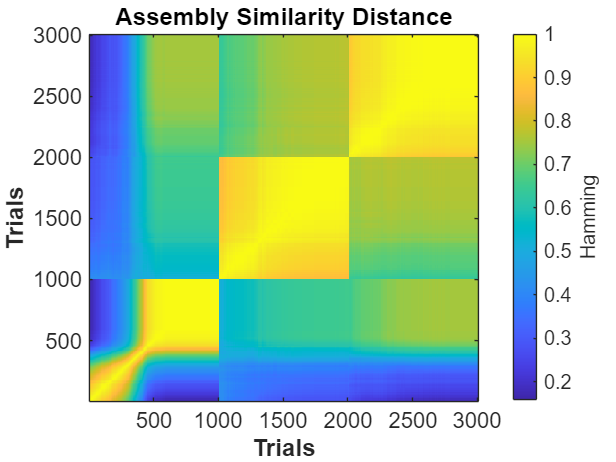

%% Similarity matrix of assembly representation excluding inhibitory cells (because of the bias they cause)
mat = 1- squareform(pdist(1*assemblies(:, 1:Ne), "Hamming"));
figure; imagesc(mat); cb = colorbar(); cb.Label.String = "Hamming";
xlabel("Trials", FontWeight="bold"); ylabel("Trials", FontWeight="bold");
title("Assembly Similarity Distance")
set(gca, 'ydir', 'normal', 'FontSize', 15);

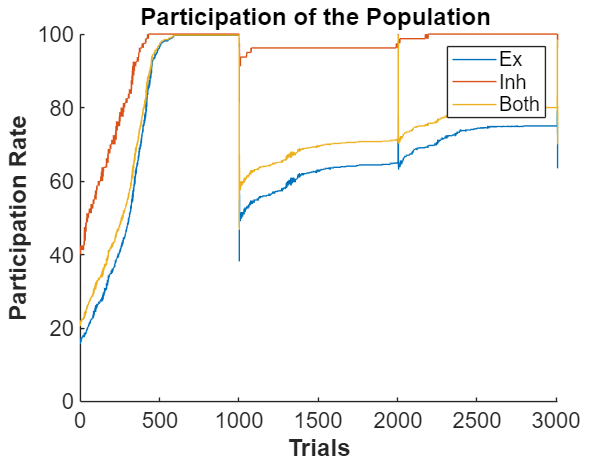



%% Participation Rate of the Population
figure; hold on;
plot(100*sum(assemblies(:, 1:Ne), 2)/Ne, DisplayName="Ex");
plot(100*sum(assemblies(:, Ne+1:end), 2)/Ni, DisplayName="Inh");
plot(100*sum(assemblies, 2)/N, DisplayName="Both");
legend(); xlabel("Trials", 'FontWeight', 'bold'); ylabel("Participation Rate", 'FontWeight', 'bold');
title("Participation of the Population ")
set(gca, 'FontName', 'arial', 'fontsize', 15)